## Taller 2 - Punto 3

clc
clear all

opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Mensual";
opts.DataRange = "A2:B277";

% Specify column names and types
opts.VariableNames = ["FECHA", "REMESAS"];
opts.VariableTypes = ["datetime", "double"];

% Specify variable properties
opts = setvaropts(opts, "FECHA", "InputFormat", "");

% Import the data
tributarios = readtable("D:\andres compu\materias\semestre 2022 - 1\series de tiempo para pronosticos de economia y finanzas\taller 2\tributarios.xlsx", opts, "UseExcel", false)

tributarios = 276×2 table
       FECHA        REMESAS  
    ___________    __________

    01-Jan-2000    1.8095e+06
    01-Feb-2000    1.4164e+06
    01-Mar-2000    1.6016e+06
    01-Apr-2000    1.6622e+06
    01-May-2000    1.6865e+06
    01-Jun-2000    1.6352e+06
    01-Jul-2000     1.692e+06
    01-Aug-2000    1.5134e+06
    01-Sep-2000    1.8161e+06
    01-Oct-2000    1.3374e+06
    01-Nov-2000    1.8254e+06
    01-Dec-2000    1.3003e+06
    01-Jan-2001    2.2869e+06
    01-Feb-2001    1.8719e+06
    01-Mar-2001    2.0809e+06
    01-Apr-2001    2.4393e+06



tributarios.lnREMESAS= log(tributarios.REMESAS)

tributarios = 276×3 table
       FECHA        REMESAS      lnREMESAS
    ___________    __________    _________

    01-Jan-2000    1.8095e+06     14.409  
    01-Feb-2000    1.4164e+06     14.164  
    01-Mar-2000    1.6016e+06     14.287  
    01-Apr-2000    1.6622e+06     14.324  
    01-May-2000    1.6865e+06     14.338  
    01-Jun-2000    1.6352e+06     14.307  
    01-Jul-2000     1.692e+06     14.341  
    01-Aug-2000    1.5134e+06      14.23  
    01-Sep-2000    1.8161e+06     14.412  
    01-Oct-2000    1.3374e+06     14.106  
    01-Nov-2000    1.8254e+06     14.417  
    01-Dec-2000    1.3003e+06     14.078  
    01-Jan-2001    2.2869e+06     14.643  
    01-Feb-2001    1.8719e+06     14.442  
    01-Mar-2001    2.0809e+06     14.548  
    01-Apr-2001    2.4393e+06     14.707  


N=length(tributarios.lnREMESAS)

N = 276


time=linspace(1,N,N)

time =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


tributarios.Time=transpose(time)

tributarios = 276×4 table
       FECHA        REMESAS      lnREMESAS    Time
    ___________    __________    _________    ____

    01-Jan-2000    1.8095e+06     14.409        1 
    01-Feb-2000    1.4164e+06     14.164        2 
    01-Mar-2000    1.6016e+06     14.287        3 
    01-Apr-2000    1.6622e+06     14.324        4 
    01-May-2000    1.6865e+06     14.338        5 
    01-Jun-2000    1.6352e+06     14.307        6 
    01-Jul-2000     1.692e+06     14.341        7 
    01-Aug-2000    1.5134e+06      14.23        8 
    01-Sep-2000    1.8161e+06     14.412        9 
    01-Oct-2000    1.3374e+06     14.106       10 
    01-Nov-2000    1.8254e+06     14.417       11 
    01-Dec-2000    1.3003e+06     14.078       12 
    01-Jan-2001    2.2869e+06     14.643       13 
    01-Feb-2001    1.8719e+06     14.442       14 
    01-Mar-2001    2.


%%


modelolin=fitlm(tributarios(1:264,:),'REMESAS~Time')

modelolin = Linear regression model:
    REMESAS ~ 1 + Time

Estimated Coefficients:
                    Estimate         SE        tStat      pValue  
                   __________    __________    ______    _________

    (Intercept)    5.8448e+05    2.5666e+05    2.2772     0.023579
    Time                50442        1679.1     30.04    7.667e-87


Number of observations: 264, Error degrees of freedom: 262
Root Mean Squared Error: 2.08e+06
R-squared: 0.775,  Adjusted R-Squared: 0.774
F-statistic vs. constant model: 902, p-value = 7.67e-87

betaslin=modelolin.Coefficients.Estimate

betaslin = 	1.0e+05 *

    5.8448
    0.5044



tributarios.time2=tributarios.Time.^2;
modelocuad=fitlm(tributarios(2:264,:),'REMESAS~Time+time2')

modelocuad = Linear regression model:
    REMESAS ~ 1 + Time + time2

Estimated Coefficients:
                    Estimate        SE        tStat       pValue  
                   __________    _________    ______    __________

    (Intercept)    1.1114e+06    3.922e+05    2.8337     0.0049625
    Time                38388         6805    5.6412    4.4017e-08
    time2              45.699       24.788    1.8436      0.066379


Number of observations: 263, Error degrees of freedom: 260
Root Mean Squared Error: 2.07e+06
R-squared: 0.777,  Adjusted R-Squared: 0.775
F-statistic vs. constant model: 453, p-value = 2.08e-85

betascuad=modelocuad.Coefficients.Estimate

betascuad = 	1.0e+06 *

    1.1114
    0.0384
    0.0000




modelolog=fitlm(tributarios(1:265,:),'lnREMESAS~Time')

modelolog = Linear regression model:
    lnREMESAS ~ 1 + Time

Estimated Coefficients:
                   Estimate         SE        tStat       pValue   
                   _________    __________    ______    ___________

    (Intercept)       14.516      0.031782    456.76              0
    Time           0.0081501    0.00020714    39.346    3.3938e-112


Number of observations: 265, Error degrees of freedom: 263
Root Mean Squared Error: 0.258
R-squared: 0.855,  Adjusted R-Squared: 0.854
F-statistic vs. constant model: 1.55e+03, p-value = 3.39e-112

betaslog=modelolog.Coefficients.Estimate

betaslog =    14.5165
    0.0082





%Selección del mejor modelo:

MODELOS = {'Modelolin';'Modelocuad'; 'Modelolog'};

AIC=[modelolin.ModelCriterion.AIC;modelocuad.ModelCriterion.AIC;;modelolog.ModelCriterion.AIC];

BIC=[modelolin.ModelCriterion.BIC;modelocuad.ModelCriterion.BIC;;modelolog.ModelCriterion.BIC];

CRITERIO = table(AIC,BIC,'RowNames',MODELOS)

CRITERIO = 3×2 table
                   AIC       BIC  
                  ______    ______

    Modelolin     8432.3    8439.4
    Modelocuad    8399.6    8410.3
    Modelolog      35.89     43.05



%El mejor modelo, según parece, es el modelolog. Este presenta un mayor
%R-squared y menor AIC y BIC.



tbl = table(tributarios.Time(1:265,:),tributarios.REMESAS(1:265,:));

modelfun = @(b,x)b(1)*exp(b(2)*x(:,1));
beta0 = [betaslin'];
%% Modelo3 = fitnlm(tributarios.Time,tributarios.REMESAS,modelfun,beta0)


# Poniendole estacionalidad

%Ya con el modelo anterior, pasamos a ponerle estacionalidad.


tributarios.MES=month(tributarios.FECHA, 'name');
tributarios.MES = categorical(tributarios.MES);

modeloremesas=fitlm(tributarios(1:265,:),'lnREMESAS~Time+MES')

modeloremesas = Linear regression model:
    lnREMESAS ~ 1 + Time + MES

Estimated Coefficients:
                     Estimate         SE         tStat        pValue   
                     _________    __________    ________    ___________

    (Intercept)         14.703      0.042142      348.89              0
    Time              0.008175    0.00014264       57.31    1.4904e-146
    MES_August        -0.36706       0.05352     -6.8584     5.3553e-11
    MES_December      -0.49602      0.053529     -9.2663     8.8804e-18
    MES_February      -0.38262      0.053518     -7.1493     9.4125e-12
    MES_January       0.052173      0.052934     0.98562        0.32527
    MES_July          -0.18381      0.053519     -3.4346     0.00069384




MODELOS2 = {'Modelolin';'Modelocuad'; 'Modelolog';'Modeloremesas'};

AIC2=[modelolin.ModelCriterion.AIC;modelocuad.ModelCriterion.AIC;;modelolog.ModelCriterion.AIC;modeloremesas.ModelCriterion.AIC];

BIC2=[modelolin.ModelCriterion.BIC;modelocuad.ModelCriterion.BIC;;modelolog.ModelCriterion.BIC;modeloremesas.ModelCriterion.BIC];

CRITERIO = table(AIC2,BIC2,'RowNames',MODELOS2)

CRITERIO = 4×2 table
                      AIC2       BIC2  
                     _______    _______

    Modelolin         8432.3     8439.4
    Modelocuad        8399.6     8410.3
    Modelolog          35.89      43.05
    Modeloremesas    -151.56    -105.02



%El modelo con estacionalidad tiene unos AIC y BIC más negativos. Además,
%tiene un mayor R-squared.


## Punto 3.3

%Estimacion del modelo

Coeficientes_modeloremesas=modeloremesas.Coefficients.Estimate

Coeficientes_modeloremesas =    14.7027
    0.0082
   -0.3671
   -0.4960
   -0.3826
    0.0522
   -0.1838
   -0.0281
   -0.2463
   -0.0400


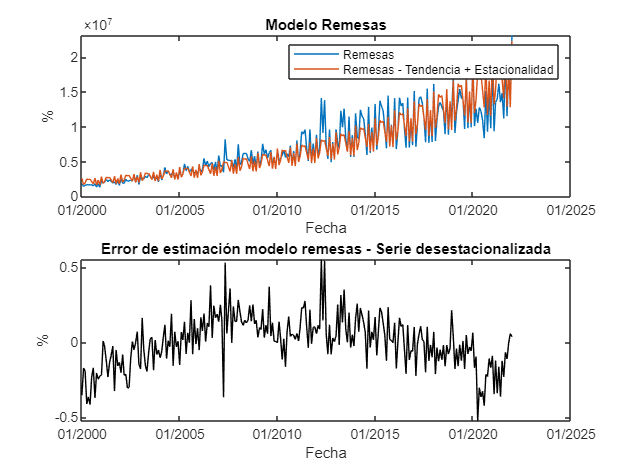



tributarios.lnREMESAS_estimado=Coeficientes_modeloremesas(1,1)+Coeficientes_modeloremesas(2,1).*tributarios.Time ...
    +(Coeficientes_modeloremesas(3,1).*(tributarios.MES=='August')) ...
    +(Coeficientes_modeloremesas(4,1).*(tributarios.MES=='December'))...
    +(Coeficientes_modeloremesas(5,1).*(tributarios.MES=='February')) ...
    +(Coeficientes_modeloremesas(6,1).*(tributarios.MES=='January')) ...
    +(Coeficientes_modeloremesas(7,1).*(tributarios.MES=='July')) ...
    +(Coeficientes_modeloremesas(8,1).*(tributarios.MES=='June')) ...
    +(Coeficientes_modeloremesas(9,1).*(tributarios.MES=='March')) ...
    +(Coeficientes_modeloremesas(10,1).*(tributarios.MES=='May')) ...
    +(Coeficientes_modeloremesas(11,1).*(tributarios.MES=='November')) ...
    +(Coeficientes_modeloremesas(12,1).*(tributarios.MES=='October')) ...
    +(Coeficientes_modeloremesas(13,1).*(tributarios.MES=='September'))...
    ...
    ;




tributarios.REMESAS_estimado=exp(Coeficientes_modeloremesas(1,1)+Coeficientes_modeloremesas(2,1).*tributarios.Time ...
    +(Coeficientes_modeloremesas(3,1).*(tributarios.MES=='August')) ...
    +(Coeficientes_modeloremesas(4,1).*(tributarios.MES=='December'))...
    +(Coeficientes_modeloremesas(5,1).*(tributarios.MES=='February')) ...
    +(Coeficientes_modeloremesas(6,1).*(tributarios.MES=='January')) ...
    +(Coeficientes_modeloremesas(7,1).*(tributarios.MES=='July')) ...
    +(Coeficientes_modeloremesas(8,1).*(tributarios.MES=='June')) ...
    +(Coeficientes_modeloremesas(9,1).*(tributarios.MES=='March')) ...
    +(Coeficientes_modeloremesas(10,1).*(tributarios.MES=='May')) ...
    +(Coeficientes_modeloremesas(11,1).*(tributarios.MES=='November')) ...
    +(Coeficientes_modeloremesas(12,1).*(tributarios.MES=='October')) ...
    +(Coeficientes_modeloremesas(13,1).*(tributarios.MES=='September'))...
    ...
    );





%Gráfica desestacionalizada (Ver código en MLX de desempleo.


figure

subplot(2,1,1)
plot(tributarios.FECHA(1:265,:), tributarios.REMESAS(1:265,:), tributarios.FECHA(1:265,:), tributarios.REMESAS_estimado(1:265,:))
title('Modelo Remesas')
xlabel('Fecha') 
ylabel('%') 
legend('Remesas','Remesas - Tendencia + Estacionalidad','Location','NorthEast')
datetick('x','mm/yyyy');


subplot(2,1,2)
plot(tributarios.FECHA(1:265,:),modeloremesas.Residuals.Raw(1:265,:),'Color','k')
title('Error de estimación modelo remesas - Serie desestacionalizada')
xlabel('Fecha') 
ylabel('%') 
datetick('x','mm/yyyy');

## Punto 3.4

%Para ciclos: probar si el residual de "modeloremesas" se comporta como
%ruido blanco --> que sea proceso estacionario. Si no, le metemos
%componente cíclico.
    %Para esto, mirar la PACF y ACF, y hacer prueba (ver).


    subplot(2,1,1)
autocorr(tributarios.REMESAS_estimado)
ylabel('ACF')
xlabel('Rezago')
title('ACF')

subplot(2,1,2)
parcorr(tributarios.REMESAS_estimado)
ylabel('PACF')
xlabel('Rezago')
title('PACF')



%Mirar el ARIMA más óptimo.

%Puede ser un AR(5) o AR(6). Quizás se pueda diferenciar aún el modelo.

    %Transformar serie para que sea estacionaria:
    tributarios.residuales_modeloremesas(1:265)=modeloremesas.Residuals.Raw

tributarios = 276×12 table
       FECHA        REMESAS      lnREMESAS    Time    time2       MES       lnREMESAS_estimado    REMESAS_estimado    residuales_modeloremesas    dresiduals    residualesAIC    residualesAIC_2
    ___________    __________    _________    ____    _____    _________    __________________    ________________    ________________________    __________    _____________    _______________

    01-Jan-2000    1.8095e+06     14.409        1        1     January            14.763             2.5792e+06               -0.35444                  NaN         -0.0135       

    

    tributarios.dresiduals=[NaN(1,1); diff(tributarios.residuales_modeloremesas)];

tributarios.dresiduals(266:276)=NaN

tributarios = 276×12 table
       FECHA        REMESAS      lnREMESAS    Time    time2       MES       lnREMESAS_estimado    REMESAS_estimado    residuales_modeloremesas    dresiduals    residualesAIC    residualesAIC_2
    ___________    __________    _________    ____    _____    _________    __________________    ________________    ________________________    __________    _____________    _______________

    01-Jan-2000    1.8095e+06     14.409        1        1     January            14.763             2.5792e+06               -0.35444                  NaN         -0.0135       


tributarios.residuales_modeloremesas(266:276)=NaN

tributarios = 276×12 table
       FECHA        REMESAS      lnREMESAS    Time    time2       MES       lnREMESAS_estimado    REMESAS_estimado    residuales_modeloremesas    dresiduals    residualesAIC    residualesAIC_2
    ___________    __________    _________    ____    _____    _________    __________________    ________________    ________________________    __________    _____________    _______________

    01-Jan-2000    1.8095e+06     14.409        1        1     January            14.763             2.5792e+06               -0.35444                  NaN         -0.0135       


% Estimemos diferentes modelos autoregresivos y guardemos sus criterios de
% información AIC y BIC para ver cual es el mejor:

AR=12;
MA=4;
LL=NaN(AR+2,MA+2);
NBetas=NaN(AR+2,MA+2);


for i=0:AR
    LL(i+2,1)=i;
    NBetas(i+2,1)=i;
        for j=0:MA   
            LL(1,j+2)=j
            NBetas(1,j+2)=j
            Mdl = arima(i,1,j);
            [EstMdl,~,Logl] = estimate(Mdl,tributarios.residuales_modeloremesas);
            param=i+j+1;
            NBetas(i+2,j+2)=param;
            LL(i+2,j+2)=Logl;
    end
end

LL =    NaN     0   NaN   NaN   NaN   NaN
     0   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


NBetas =    NaN     0   NaN   NaN   NaN   NaN
     0   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0014578       0.011171        0.1305         0.89617
    Variance     0.032628      0.0020858        15.643      3.7171e-55



LL =        NaN         0    1.0000       NaN       NaN       NaN
         0   77.4728       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1   NaN   NaN   NaN
     0     1   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    0.00088674      0.0013351       0.66416          0.50659
    MA{1}         -0.83649       0.033353        -25.08      8.2861e-139
    Variance      0.017329       0.001145        15.135       9.5703e-52



LL =        NaN         0    1.0000    2.0000       NaN       NaN
         0   77.4728  161.3163       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2   NaN   NaN
     0     1     2   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(0,1,2) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00099142       0.001543       0.64251         0.52054
    MA{1}         -0.90898       0.052375       -17.355      1.7974e-67
    MA{2}         0.096505       0.053352        1.8088        0.070478
    Variance      0.017107      0.0011254        15.201      3.4668e-52



LL =        NaN         0    1.0000    2.0000    3.0000       NaN
         0   77.4728  161.3163  163.0264       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3   NaN
     0     1     2     3   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(0,1,3) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00086997      0.0013396       0.64942         0.51607
    MA{1}         -0.91447        0.05316       -17.202       2.552e-66
    MA{2}          0.26175        0.08384         3.122        0.001796
    MA{3}         -0.18352        0.07372       -2.4894        0.012796
    Variance      0.016447      0.0010777        15.261      1.3909e-52



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(0,1,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00089057      0.0013676       0.65118         0.51493
    MA{1}         -0.91735       0.053675       -17.091      1.7393e-65
    MA{2}          0.26598       0.084222        3.1581       0.0015878
    MA{3}         -0.22405       0.095072       -2.3566        0.018442
    MA{4}          0.04313       0.066899        0.6447         0.51912
    Variance      0.016418      0.0010768        15.247      1.7167e-52



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0018313      0.0087404       0.20952         0.83404
    AR{1}        -0.64397       0.040044       -16.082      3.4394e-58
    Variance      0.01917      0.0011816        16.223      3.4558e-59



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0011517       0.001976       0.58286         0.55999
    AR{1}        -0.19304       0.064346       -3.0001       0.0026992
    MA{1}        -0.75806       0.043893       -17.271      7.8043e-67
    Variance     0.016936      0.0011062         15.31       6.541e-53



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(1,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0013442      0.0026491       0.50743         0.61185
    AR{1}        -0.98434       0.015563       -63.249               0
    MA{1}         0.10977       0.042416        2.5881       0.0096516
    MA{2}        -0.77402       0.041237        -18.77      1.3338e-78
    Variance     0.016056      0.0010025        16.016      9.8975e-58



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(1,1,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0013832      0.0028191       0.49064         0.62368
    AR{1}        -0.98528       0.015584       -63.224               0
    MA{1}        0.097525       0.048153        2.0253        0.042836
    MA{2}         -0.7715        0.04094       -18.844      3.2664e-79
    MA{3}        0.019842       0.053179       0.37312         0.70906
    Variance     0.016048      0.0010158        15.799      3.1601e-56



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(1,1,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0012466      0.0025673       0.48557         0.62727
    AR{1}        -0.98748       0.013985       -70.609               0
    MA{1}        0.088125       0.050838        1.7334        0.083018
    MA{2}        -0.65988       0.060818        -10.85        1.99e-27
    MA{3}        0.020333       0.052563       0.38684         0.69888
    MA{4}        -0.13649       0.068777       -1.9845          0.0472
    Variance     0.015741      0.0010269        15.328      4.9416e-53



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(2,1,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.002039      0.0084798       0.24046         0.80998
    AR{1}       -0.78751       0.048712       -16.167      8.6668e-59
    AR{2}       -0.22313       0.058382       -3.8219      0.00013245
    Variance    0.018223      0.0012013         15.17      5.5922e-52



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(2,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00063755      0.0010838        0.58824        0.55637
    AR{1}        -0.061985       0.068877       -0.89992        0.36816
    AR{2}          0.23896       0.084461         2.8292      0.0046664
    MA{1}         -0.86777       0.054362        -15.963     2.3273e-57
    Variance      0.016317      0.0010512         15.522     2.4724e-54



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(2,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0013777      0.0027983        0.49234        0.62248
    AR{1}        -0.99829       0.071598        -13.943     3.4704e-44
    AR{2}       -0.013522        0.06557       -0.20622        0.83662
    MA{1}          0.1162       0.060264         1.9282        0.05383
    MA{2}        -0.77076       0.042852        -17.987     2.4807e-72
    Variance     0.016054      0.0010174          15.78     4.2626e-56



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0013496      0.0029449       0.45828         0.64675
    AR{1}        -0.60306        0.12748       -4.7307      2.2377e-06
    AR{2}        -0.68829        0.12164       -5.6584      1.5276e-08
    MA{1}        -0.29527        0.11588        -2.548        0.010835
    MA{2}         0.36927       0.096039        3.8449      0.00012058
    MA{3}        -0.71037       0.082028       -8.6601       4.715e-18
    Variance     0.016168      0.0010518        15.371      2.5518e-53



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(2,1,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00098337      0.0019674       0.49983         0.61719
    AR{1}         -0.72396        0.38658       -1.8727        0.061104
    AR{2}          0.26331        0.38597       0.68222          0.4951
    MA{1}         -0.16558        0.38714       -0.4277         0.66887
    MA{2}         -0.69089       0.082891       -8.3349      7.7562e-17
    MA{3}          0.22402        0.30461       0.73545         0.46206
    MA{4}         -0.13917       0.066399        -2.096         0.03608
    Variance      0.015682 

LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(3,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0024828      0.0083531       0.29723         0.76629
    AR{1}        -0.82916       0.048548       -17.079       2.115e-65
    AR{2}        -0.37724       0.074309       -5.0767      3.8407e-07
    AR{3}        -0.19723        0.05727       -3.4439      0.00057339
    Variance     0.017535      0.0011159        15.714      1.2069e-55



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(3,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00066164      0.0011293        0.58589        0.55795
    AR{1}        -0.063659       0.072206       -0.88164        0.37797
    AR{2}          0.23478       0.091788         2.5579       0.010532
    AR{3}       -0.0097569       0.074479         -0.131        0.89577
    MA{1}         -0.86433       0.062428        -13.845     1.3599e-43
    Variance      0.016316      0.0010543         15.476     5.0216e-54



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(3,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0010317      0.0021354       0.48314           0.629
    AR{1}        -0.95934       0.071487        -13.42      4.6365e-41
    AR{2}         0.14958        0.11766        1.2713         0.20362
    AR{3}         0.12612         0.0776        1.6253          0.1041
    MA{1}        0.075472        0.06371        1.1846         0.23617
    MA{2}        -0.81397         0.0556        -14.64      1.5647e-48
    Variance     0.015887      0.0010341        15.363      2.8846e-53



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(3,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.001511       0.003603       0.41938         0.67494
    AR{1}        -0.5144       0.068903       -7.4655      8.2961e-14
    AR{2}       -0.83099       0.062063       -13.389      6.9688e-41
    AR{3}       -0.17146       0.072797       -2.3553        0.018509
    MA{1}        -0.4099       0.058833       -6.9673      3.2317e-12
    MA{2}         0.6053       0.050632        11.955      6.1232e-33
    MA{3}        -0.7435       0.048893       -15.207      3.1906e-52
    Variance     0.01603      0.0010751      

LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(3,1,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0013864      0.0026595        0.52128        0.60217
    AR{1}        -0.77618        0.41866        -1.8539       0.063747
    AR{2}        0.036527        0.54745       0.066723         0.9468
    AR{3}        -0.17754         0.2485       -0.71445        0.47495
    MA{1}        -0.11262        0.41648       -0.27041        0.78684
    MA{2}        -0.52308        0.26596        -1.9668       0.049205
    MA{3}         0.21098        0.30954         0.6816        0.49549
    MA{4}        -0.26683        0.2

LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(4,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0028195      0.0083225       0.33878         0.73478
    AR{1}        -0.84948        0.05083       -16.712      1.0707e-62
    AR{2}        -0.41654       0.075369       -5.5266      3.2642e-08
    AR{3}        -0.28642       0.083558       -3.4278      0.00060842
    AR{4}        -0.10727       0.070183       -1.5284         0.12641
    Variance      0.01734      0.0011414        15.192      3.9946e-52



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(4,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00065818      0.0011391        0.57783        0.56338
    AR{1}         -0.06307       0.080159       -0.78681         0.4314
    AR{2}          0.23501       0.092059         2.5528       0.010685
    AR{3}       -0.0092008       0.080392       -0.11445        0.90888
    AR{4}        0.0017865       0.066195       0.026988        0.97847
    MA{1}          -0.8649       0.069903        -12.373     3.6635e-35
    Variance      0.016316      0.0010684         15.271     1.1862e-52



LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas =    NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(4,1,2) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00085659      0.0019194       0.44629         0.65539
    AR{1}          -0.9413       0.081642        -11.53      9.3618e-31
    AR{2}          0.17238        0.12673        1.3602         0.17377
    AR{3}          0.18763        0.13545        1.3852         0.16598
    AR{4}         0.054233       0.094005       0.57691           0.564
    MA{1}         0.052683       0.083235       0.63294         0.52677
    MA{2}         -0.82132       0.057734       -14.226      6.3284e-46
    Variance      0.015854 

LL =        NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(4,1,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0011426      0.0026425       0.43239         0.66546
    AR{1}        -0.66864       0.080169       -8.3404      7.4042e-17
    AR{2}        -0.68573        0.12685        -5.406      6.4462e-08
    AR{3}         0.08072        0.12051       0.66982         0.50297
    AR{4}         0.14369       0.085355        1.6834        0.092291
    MA{1}        -0.25382       0.071809       -3.5346      0.00040835
    MA{2}         0.37678       0.076794        4.9064      9.2768e-07
    MA{3}        -0.79829       0.05

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(4,1,4) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic       PValue  
                ___________    _____________    ___________    __________

    Constant      0.0013151      0.002657           0.49494       0.62064
    AR{1}          -0.82032       0.48335           -1.6972      0.089668
    AR{2}       -0.00053242       0.60634       -0.00087808        0.9993
    AR{3}          -0.14601       0.26416          -0.55276       0.58043
    AR{4}          0.024502       0.11512           0.21284       0.83145
    MA{1}         -0.065466       0.48111          -0.13607       0.89176
    MA{2}          -0.52909       0.26481            -1.998       0.04572
    MA{3}   

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(5,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0031874      0.0082299       0.38729         0.69854
    AR{1}         -0.8637       0.051039       -16.922       3.073e-64
    AR{2}        -0.45529         0.0722       -6.3059      2.8657e-10
    AR{3}        -0.34346       0.083854       -4.0959      4.2047e-05
    AR{4}        -0.22427       0.082564       -2.7163       0.0066008
    AR{5}        -0.13654       0.065217       -2.0936        0.036292
    Variance     0.017031      0.0011011        15.467      5.8139e-54



LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(5,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00083126      0.0013759        0.60416        0.54574
    AR{1}        -0.091442       0.090239        -1.0133         0.3109
    AR{2}          0.20548        0.10015         2.0517       0.040196
    AR{3}        -0.013676        0.08198       -0.16682        0.86751
    AR{4}        -0.018768       0.069297       -0.27083        0.78652
    AR{5}        -0.072042       0.083723       -0.86048        0.38953
    MA{1}          -0.8369       0.082468        -10.148     3.3754e-24
    Variance       0.01625 

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(5,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0010174      0.0022271        0.45683        0.64779
    AR{1}        -0.93861       0.088647        -10.588     3.3809e-26
    AR{2}         0.14767        0.13133         1.1245        0.26082
    AR{3}         0.16735        0.13681         1.2232        0.22126
    AR{4}        -0.02647        0.11815       -0.22405        0.82272
    AR{5}       -0.079352       0.067238        -1.1802        0.23793
    MA{1}        0.049848       0.089388        0.55766        0.57707
    MA{2}        -0.78206       0.07

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(5,1,3) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00093912      0.0015791        0.59471        0.55204
    AR{1}         -0.23248        0.17621        -1.3193        0.18706
    AR{2}          0.81684        0.15951         5.1209     3.0403e-07
    AR{3}        -0.026976       0.096439       -0.27972        0.77969
    AR{4}         -0.26434       0.073541        -3.5945     0.00032503
    AR{5}         -0.17004       0.083734        -2.0307       0.042285
    MA{1}         -0.65368        0.16832        -3.8834     0.00010299
    MA{2}         -0.82218 

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(5,1,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0013349      0.0027551        0.48451        0.62802
    AR{1}        -0.84059        0.60392        -1.3919        0.16396
    AR{2}       -0.060139        0.80695      -0.074525        0.94059
    AR{3}        -0.18433        0.30196       -0.61046        0.54156
    AR{4}        0.051413        0.18514         0.2777        0.78125
    AR{5}        0.025161       0.095214        0.26425        0.79158
    MA{1}       -0.045845        0.59967      -0.076451        0.93906
    MA{2}        -0.48481        0.3

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(6,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0032634         0.0082        0.39798        0.69064
    AR{1}        -0.87035        0.05161        -16.864     8.2972e-64
    AR{2}        -0.46564       0.072331        -6.4376     1.2136e-10
    AR{3}        -0.35951       0.090975        -3.9518     7.7572e-05
    AR{4}        -0.24661       0.094363        -2.6134      0.0089643
    AR{5}        -0.17958       0.095779        -1.8749       0.060806
    AR{6}       -0.049332        0.07381       -0.66836         0.5039
    Variance     0.016992      0.001

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(6,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0009222      0.0015071         0.6119         0.5406
    AR{1}          -0.109        0.11905       -0.91554        0.35991
    AR{2}         0.18936        0.12884         1.4697        0.14164
    AR{3}       -0.024411       0.093656       -0.26065        0.79436
    AR{4}       -0.020095       0.072238       -0.27818        0.78087
    AR{5}        -0.08269         0.0898       -0.92082        0.35714
    AR{6}       -0.034484        0.08358       -0.41259        0.67991
    MA{1}        -0.82136        0.1

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(6,1,2) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00092815      0.0020587        0.45084        0.65211
    AR{1}         -0.91803        0.10195        -9.0048     2.1606e-19
    AR{2}          0.17101         0.1554         1.1004        0.27115
    AR{3}          0.17988        0.15585         1.1542        0.24841
    AR{4}        -0.018842        0.12915        -0.1459          0.884
    AR{5}        -0.037944        0.13138       -0.28881        0.77273
    AR{6}         0.041578       0.094064        0.44202        0.65847
    MA{1}         0.030839 

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(6,1,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0014149      0.0020947       0.67547         0.49938
    AR{1}        -0.19756        0.10737         -1.84        0.065773
    AR{2}         0.83168        0.12277         6.774      1.2526e-11
    AR{3}       -0.088168       0.085525       -1.0309         0.30259
    AR{4}        -0.27155       0.080524       -3.3723      0.00074548
    AR{5}        -0.24528       0.089715        -2.734       0.0062566
    AR{6}        -0.10606       0.069051       -1.5359         0.12455
    MA{1}         -0.7035         0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(6,1,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0014639      0.0038928       0.37605         0.70688
    AR{1}         -1.3171       0.090461       -14.559      5.0932e-48
    AR{2}         -1.0252         0.1464       -7.0027        2.51e-12
    AR{3}        -0.52396        0.21833       -2.3999        0.016401
    AR{4}         0.33293         0.2186        1.5231         0.12775
    AR{5}         0.32042        0.16746        1.9134        0.055691
    AR{6}         0.15661        0.10014         1.564         0.11782
    MA{1}         0.43796       0.08

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(7,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0031401      0.0081089       0.38724         0.69858
    AR{1}        -0.88007       0.051359       -17.136       8.062e-66
    AR{2}        -0.49658       0.072786       -6.8225      8.9481e-12
    AR{3}        -0.39892       0.092505       -4.3124      1.6149e-05
    AR{4}        -0.30641       0.094144       -3.2547       0.0011351
    AR{5}        -0.26148        0.10249       -2.5513        0.010732
    AR{6}         -0.2011         0.1003        -2.005        0.044962
    AR{7}        -0.17031       0.06

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(7,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0013175      0.0021377        0.61631        0.53769
    AR{1}        -0.19249        0.13096        -1.4699         0.1416
    AR{2}        0.099652        0.13992        0.71221        0.47633
    AR{3}       -0.078359       0.096273       -0.81393        0.41569
    AR{4}       -0.061261       0.072518       -0.84477        0.39824
    AR{5}       -0.095007       0.094816         -1.002        0.31634
    AR{6}       -0.089553       0.085528        -1.0471        0.29507
    AR{7}        -0.15192       0.08

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(7,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0011873      0.0029551        0.40178        0.68785
    AR{1}        -0.92932        0.13394        -6.9384      3.965e-12
    AR{2}        0.060198        0.20074        0.29989        0.76426
    AR{3}        0.083168        0.17266        0.48168        0.63003
    AR{4}       -0.074298        0.12559        -0.5916        0.55412
    AR{5}        -0.08912        0.13267       -0.67176        0.50174
    AR{6}        -0.13218        0.14525       -0.91004         0.3628
    AR{7}        -0.16481       0.08

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(7,1,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0014095      0.0032263        0.43688         0.6622
    AR{1}        -0.42828        0.10835        -3.9526     7.7308e-05
    AR{2}        -0.66184        0.12991        -5.0947     3.4924e-07
    AR{3}       -0.071949        0.15734       -0.45727        0.64747
    AR{4}        0.092972        0.13215        0.70355        0.48171
    AR{5}         -0.1142        0.12236       -0.93335        0.35064
    AR{6}        -0.11269       0.089308        -1.2618        0.20701
    AR{7}        -0.22625       0.09

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11   NaN
   NaN   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(7,1,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0011988      0.0028463        0.42119        0.67361
    AR{1}         0.23442        0.17731         1.3221        0.18612
    AR{2}        -0.36319        0.12308        -2.9507      0.0031701
    AR{3}         0.31799        0.11172         2.8462      0.0044241
    AR{4}       -0.039211        0.07597       -0.51614        0.60575
    AR{5}        -0.32426       0.088538        -3.6623     0.00024993
    AR{6}        -0.18154       0.078402        -2.3155       0.020584
    AR{7}        -0.26945       0.08

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000       NaN       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8   NaN   NaN   NaN   NaN   NaN


 
    ARIMA(8,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0031844      0.0080647        0.39485        0.69295
    AR{1}        -0.88972       0.052301        -17.011     6.7605e-65
    AR{2}        -0.50911       0.073604        -6.9168     4.6183e-12
    AR{3}        -0.41564       0.094029        -4.4203     9.8548e-06
    AR{4}        -0.32458       0.095871        -3.3856     0.00071028
    AR{5}        -0.28555        0.10618        -2.6894       0.007159
    AR{6}         -0.2322        0.10338        -2.2461       0.024696
    AR{7}        -0.22616       0.09

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985       NaN       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9   NaN   NaN   NaN   NaN


 
    ARIMA(8,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0013917      0.0022588        0.61612        0.53781
    AR{1}        -0.20664        0.16806        -1.2295        0.21887
    AR{2}        0.087294        0.17498        0.49886        0.61788
    AR{3}       -0.086611        0.11889       -0.72849        0.46631
    AR{4}        -0.06755       0.089831       -0.75197        0.45207
    AR{5}        -0.10051         0.1008       -0.99712         0.3187
    AR{6}        -0.09267       0.088929        -1.0421        0.29738
    AR{7}         -0.1594       0.09

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096       NaN       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10   NaN   NaN   NaN


 
    ARIMA(8,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0012247       0.00307         0.39892        0.68995
    AR{1}        -0.94027       0.16309         -5.7653     8.1497e-09
    AR{2}        0.049389       0.23074         0.21405        0.83051
    AR{3}        0.076104       0.18979         0.40098        0.68843
    AR{4}       -0.079418       0.13466        -0.58979        0.55533
    AR{5}        -0.09238       0.13997        -0.66001        0.50925
    AR{6}        -0.13587       0.15259        -0.89048        0.37321
    AR{7}        -0.17597       0.14

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699       NaN       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11   NaN   NaN


 
    ARIMA(8,1,3) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00084613      0.0022805        0.37103        0.71062
    AR{1}       -0.0031004        0.11375      -0.027256        0.97826
    AR{2}         -0.66294        0.11569        -5.7302     1.0029e-08
    AR{3}        -0.067279        0.17393       -0.38682        0.69889
    AR{4}          0.13942        0.15132        0.92132        0.35689
    AR{5}        -0.046856         0.1443       -0.32471         0.7454
    AR{6}        -0.036381        0.12429       -0.29271        0.76974
    AR{7}        -0.030079 

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631       NaN


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12   NaN


 
    ARIMA(8,1,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0011302      0.0026561        0.42552        0.67046
    AR{1}          0.2566        0.19815          1.295        0.19533
    AR{2}        -0.34652        0.12829         -2.701      0.0069126
    AR{3}         0.33129        0.12027         2.7545      0.0058787
    AR{4}       -0.027616       0.079517       -0.34729        0.72837
    AR{5}        -0.32063       0.089077        -3.5994     0.00031895
    AR{6}        -0.16439       0.084373        -1.9483       0.051376
    AR{7}         -0.2654       0.08

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(9,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0032706      0.0079255       0.41267         0.67985
    AR{1}        -0.89977       0.051333       -17.528       8.758e-69
    AR{2}        -0.54342       0.071989       -7.5487      4.3976e-14
    AR{3}         -0.4538       0.090881       -4.9933      5.9359e-07
    AR{4}        -0.37298       0.092998       -4.0107      6.0548e-05
    AR{5}        -0.33734        0.10277       -3.2824       0.0010294
    AR{6}        -0.29901        0.10275         -2.91       0.0036138
    AR{7}        -0.31015       0.09

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(9,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0018711      0.0031349        0.59687        0.55059
    AR{1}        -0.32564         0.1958        -1.6632        0.09628
    AR{2}       -0.037889        0.18302       -0.20702        0.83599
    AR{3}        -0.16608        0.12586        -1.3196        0.18697
    AR{4}        -0.13987        0.10057        -1.3908         0.1643
    AR{5}        -0.15655        0.10454        -1.4974        0.13429
    AR{6}        -0.14546       0.090094        -1.6145        0.10642
    AR{7}        -0.19162       0.09

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(9,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant    0.0014786      0.0033862        0.43665         0.66236
    AR{1}         0.38629       0.078823         4.9007      9.5484e-07
    AR{2}        -0.13292       0.080766        -1.6458        0.099815
    AR{3}        -0.44201       0.083219        -5.3114      1.0879e-07
    AR{4}        -0.21617       0.060989        -3.5445      0.00039342
    AR{5}        -0.19771        0.08127        -2.4327        0.014985
    AR{6}        -0.15151       0.080183        -1.8895         0.05882
    AR{7}        -0.19116  

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(9,1,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0017415       0.005209       0.33433         0.73813
    AR{1}        -0.28828        0.10641       -2.7092        0.006745
    AR{2}         0.27872       0.092743        3.0053       0.0026533
    AR{3}        -0.46054       0.083152       -5.5385      3.0509e-08
    AR{4}        -0.48681       0.078445       -6.2058      5.4437e-10
    AR{5}        -0.29589       0.078248       -3.7815      0.00015591
    AR{6}        -0.24149       0.082743       -2.9186       0.0035166
    AR{7}        -0.22356       0.07

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(9,1,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0018161      0.0039036        0.46523        0.64176
    AR{1}       -0.038961        0.19056       -0.20445          0.838
    AR{2}          0.3233        0.11745         2.7527        0.00591
    AR{3}        -0.61922        0.13555        -4.5683     4.9175e-06
    AR{4}        -0.37008        0.12002        -3.0835      0.0020457
    AR{5}        -0.15947        0.13736         -1.161        0.24564
    AR{6}         -0.1788       0.099498         -1.797       0.072336
    AR{7}        -0.16676       0.07

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(10,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0032767      0.0079642        0.41143        0.68076
    AR{1}        -0.90129       0.052321        -17.226     1.6882e-66
    AR{2}        -0.54537       0.072537        -7.5185     5.5395e-14
    AR{3}        -0.45668       0.092062        -4.9606     7.0278e-07
    AR{4}        -0.37601       0.098196        -3.8292     0.00012856
    AR{5}        -0.34091        0.10704        -3.1848      0.0014485
    AR{6}        -0.30276        0.10463        -2.8937      0.0038071
    AR{7}        -0.31474        0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(10,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0020699      0.0036466        0.56763        0.57029
    AR{1}         -0.3861        0.29696        -1.3002        0.19354
    AR{2}       -0.091586        0.28207        -0.3247        0.74541
    AR{3}         -0.2055        0.18663        -1.1011        0.27085
    AR{4}        -0.17302        0.15897        -1.0884        0.27644
    AR{5}        -0.18746        0.14606        -1.2834        0.19934
    AR{6}        -0.17221        0.12946        -1.3302        0.18346
    AR{7}        -0.21811        0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(10,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant     0.002113      0.0036998       0.57111         0.56793
    AR{1}           0.275        0.11585        2.3737        0.017609
    AR{2}        -0.16332       0.088531       -1.8448        0.065062
    AR{3}        -0.46072       0.086741       -5.3114      1.0877e-07
    AR{4}        -0.24395       0.061722       -3.9525      7.7342e-05
    AR{5}        -0.22719       0.083046       -2.7358       0.0062233
    AR{6}        -0.18712       0.079855       -2.3432        0.019117
    AR{7}        -0.22876       0.0

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(10,1,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0026245      0.0040224        0.65249        0.51409
    AR{1}         0.24899        0.40893        0.60888         0.5426
    AR{2}         -0.3579        0.12414        -2.8832      0.0039369
    AR{3}        -0.46527        0.14664        -3.1729      0.0015094
    AR{4}         -0.1884        0.21279       -0.88542        0.37593
    AR{5}        -0.23007         0.1463        -1.5726         0.1158
    AR{6}        -0.19739         0.1315         -1.501        0.13335
    AR{7}        -0.24439        0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(10,1,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0028684      0.0053894       0.53223         0.59457
    AR{1}         0.29057        0.12748        2.2794        0.022642
    AR{2}        -0.75997       0.099072       -7.6709      1.7083e-14
    AR{3}        -0.14075        0.12204       -1.1533         0.24878
    AR{4}        -0.27746       0.095472       -2.9061       0.0036591
    AR{5}        -0.48517        0.10147       -4.7814      1.7408e-06
    AR{6}        -0.27519       0.080776       -3.4068      0.00065719
    AR{7}        -0.36763       0.0

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(11,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0034672      0.0071829       0.48271          0.6293
    AR{1}        -0.90758       0.045979       -19.739      9.9913e-87
    AR{2}        -0.62399       0.068842       -9.0641      1.2564e-19
    AR{3}        -0.55423       0.085344       -6.4941      8.3545e-11
    AR{4}        -0.51629       0.086135        -5.994      2.0473e-09
    AR{5}        -0.48758       0.097407       -5.0056      5.5682e-07
    AR{6}        -0.47302        0.10123       -4.6728      2.9719e-06
    AR{7}        -0.49517        0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(11,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0036245      0.0080197       0.45195          0.6513
    AR{1}        -0.99902        0.15227       -6.5607      5.3541e-11
    AR{2}         -0.7065        0.13994       -5.0486      4.4508e-07
    AR{3}          -0.604        0.11424       -5.2873      1.2412e-07
    AR{4}        -0.55868        0.11342       -4.9257      8.4054e-07
    AR{5}         -0.5232         0.1142       -4.5813      4.6213e-06
    AR{6}        -0.50558        0.11929       -4.2382      2.2534e-05
    AR{7}        -0.52384        0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(11,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0044878       0.010314       0.43512         0.66348
    AR{1}         -1.0036        0.12593       -7.9696      1.5914e-15
    AR{2}        -0.96799        0.16778       -5.7694      7.9554e-09
    AR{3}           -0.84        0.15465       -5.4316      5.5865e-08
    AR{4}        -0.70051        0.13139       -5.3316      9.7375e-08
    AR{5}        -0.64002        0.12675       -5.0493      4.4351e-07
    AR{6}        -0.59934        0.12376       -4.8427      1.2807e-06
    AR{7}        -0.61172        0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(11,1,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0047157       0.010792       0.43698         0.66213
    AR{1}         -1.0165         0.1334       -7.6198      2.5409e-14
    AR{2}        -0.97855         0.1741       -5.6207      1.9014e-08
    AR{3}        -0.88301        0.22912       -3.8539      0.00011627
    AR{4}        -0.73821        0.19597        -3.767       0.0001652
    AR{5}        -0.66175        0.15463       -4.2796      1.8727e-05
    AR{6}        -0.61681        0.14514       -4.2498      2.1394e-05
    AR{7}        -0.62556        0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(11,1,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0047931       0.010928        0.4386         0.66095
    AR{1}        -0.98172        0.13108       -7.4894       6.919e-14
    AR{2}        -0.92426        0.17279        -5.349      8.8464e-08
    AR{3}        -0.84645        0.22708       -3.7276       0.0001933
    AR{4}         -0.7822        0.23592       -3.3156      0.00091452
    AR{5}        -0.70154        0.19343       -3.6268      0.00028696
    AR{6}        -0.63384        0.15646       -4.0511      5.0984e-05
    AR{7}        -0.63817        0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(12,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0033469      0.0072178        0.4637         0.64286
    AR{1}        -0.86719       0.047022       -18.442      6.0288e-76
    AR{2}        -0.58676        0.07106       -8.2572      1.4916e-16
    AR{3}        -0.51731       0.090798       -5.6973      1.2169e-08
    AR{4}        -0.47868       0.089891       -5.3251      1.0088e-07
    AR{5}        -0.44426        0.10317       -4.3063      1.6602e-05
    AR{6}        -0.42937        0.10664       -4.0262      5.6685e-05
    AR{7}        -0.44881        0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(12,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0012299      0.0026263        0.46832        0.63955
    AR{1}        -0.19464        0.17178        -1.1331        0.25718
    AR{2}        0.024212        0.13683        0.17695        0.85955
    AR{3}       -0.089738        0.11214       -0.80025        0.42357
    AR{4}       -0.097065        0.10624       -0.91365         0.3609
    AR{5}       -0.081173        0.10734       -0.75622        0.44952
    AR{6}       -0.082225       0.092399        -0.8899        0.37352
    AR{7}        -0.11053       0.0

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(12,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0018183      0.0033679        0.53989        0.58927
    AR{1}        -0.13833        0.15135       -0.91392        0.36076
    AR{2}       -0.083394         0.1782       -0.46798         0.6398
    AR{3}        -0.20426        0.15713           -1.3        0.19361
    AR{4}        -0.16051        0.11947        -1.3435         0.1791
    AR{5}         -0.1347        0.12194        -1.1046        0.26933
    AR{6}        -0.12526        0.10029        -1.2489        0.21169
    AR{7}        -0.15305        0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(12,1,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0018239       0.003383        0.53915        0.58979
    AR{1}        -0.13839         0.2125       -0.65126        0.51488
    AR{2}       -0.082652        0.18276       -0.45226        0.65108
    AR{3}         -0.2055        0.21489        -0.9563        0.33892
    AR{4}        -0.16186        0.19543       -0.82825        0.40753
    AR{5}        -0.13544        0.16391       -0.82629        0.40864
    AR{6}        -0.12587        0.14389       -0.87479        0.38169
    AR{7}         -0.1535        0.

LL = 14×6
       NaN         0    1.0000    2.0000    3.0000    4.0000
         0   77.4728  161.3163  163.0264  168.2419  168.4766
    1.0000  147.9431  164.3570  171.4287  171.4923  174.0519
    2.0000  154.6521  169.2900  171.4428  170.5060  174.5502
    3.0000  159.7507  169.2997  172.8262  171.6466  174.9298
    4.0000  161.2333  169.3000  173.1039  172.3571  174.9706
    5.0000  163.6161  169.8364  173.6502  175.6857  174.9902
    6.0000  163.9218  169.9550  173.8217  176.5108  180.4704
    7.0000  167.5227  172.2830  176.3612  179.1767  180.7749
    8.0000  167.9985  172.3096  176.3699  182.9631  180.8512


NBetas = 14×6
   NaN     0     1     2     3     4
     0     1     2     3     4     5
     1     2     3     4     5     6
     2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10
     6     7     8     9    10    11
     7     8     9    10    11    12
     8     9    10    11    12    13


 
    ARIMA(12,1,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0021881       0.004844        0.45171        0.65148
    AR{1}        -0.19756        0.20579       -0.95998        0.33706
    AR{2}        -0.18785        0.20032       -0.93775        0.34837
    AR{3}        -0.20506        0.17024        -1.2045        0.22839
    AR{4}        -0.30485        0.19851        -1.5357        0.12462
    AR{5}        -0.29024        0.18809        -1.5431        0.12281
    AR{6}        -0.21937        0.14507        -1.5122         0.1305
    AR{7}         -0.2337        0.


NBetas(2,2)=1;
C=size(NBetas,2);
T=length(tributarios.dresiduals((~isnan(tributarios.dresiduals))))

T = 264

AIK=[];
SIC=[];
for i=2:C
   [aic,BIC] = aicbic(LL(2:end,i),NBetas(2:end,i),T) 
   AIK(:,i-1)=aic
   SIC(:,i-1)=BIC
end

aic = 13×1
 -152.9456
 -291.8862
 -303.3041
 -311.5014
 -312.4667
 -315.2323
 -313.8436
 -319.0454
 -317.9970
 -322.3534


BIC = 13×1
 -149.3696
 -284.7343
 -292.5763
 -297.1976
 -294.5869
 -293.7766
 -288.8120
 -290.4378
 -285.8135
 -286.5939


AIK = 13×1
 -152.9456
 -291.8862
 -303.3041
 -311.5014
 -312.4667
 -315.2323
 -313.8436
 -319.0454
 -317.9970
 -322.3534


SIC = 13×1
 -149.3696
 -284.7343
 -292.5763
 -297.1976
 -294.5869
 -293.7766
 -288.8120
 -290.4378
 -285.8135
 -286.5939


aic = 13×1
 -318.6326
 -322.7140
 -330.5800
 -328.5994
 -326.6001
 -325.6728
 -323.9100
 -326.5660
 -324.6192
 -327.0823


BIC = 13×1
 -311.4807
 -311.9861
 -316.2762
 -310.7197
 -305.1444
 -300.6412
 -295.3024
 -294.3824
 -288.8597
 -287.7469


AIK = 13×2
 -152.9456 -318.6326
 -291.8862 -322.7140
 -303.3041 -330.5800
 -311.5014 -328.5994
 -312.4667 -326.6001
 -315.2323 -325.6728
 -313.8436 -323.9100
 -319.0454 -326.5660
 -317.9970 -324.6192
 -322.3534 -327.0823


SIC = 13×2
 -149.3696 -311.4807
 -284.7343 -311.9861
 -292.5763 -316.2762
 -297.1976 -310.7197
 -294.5869 -305.1444
 -293.7766 -300.6412
 -288.8120 -295.3024
 -290.4378 -294.3824
 -285.8135 -288.8597
 -286.5939 -287.7469


aic = 13×1
 -320.0528
 -334.8574
 -332.8856
 -333.6523
 -332.2078
 -331.3005
 -329.6434
 -332.7224
 -330.7397
 -344.3445


BIC = 13×1
 -309.3249
 -320.5536
 -315.0059
 -312.1966
 -307.1762
 -302.6929
 -297.4599
 -296.9629
 -291.4043
 -301.4331


AIK = 13×3
 -152.9456 -318.6326 -320.0528
 -291.8862 -322.7140 -334.8574
 -303.3041 -330.5800 -332.8856
 -311.5014 -328.5994 -333.6523
 -312.4667 -326.6001 -332.2078
 -315.2323 -325.6728 -331.3005
 -313.8436 -323.9100 -329.6434
 -319.0454 -326.5660 -332.7224
 -317.9970 -324.6192 -330.7397
 -322.3534 -327.0823 -344.3445


SIC = 13×3
 -149.3696 -311.4807 -309.3249
 -284.7343 -311.9861 -320.5536
 -292.5763 -316.2762 -315.0059
 -297.1976 -310.7197 -312.1966
 -294.5869 -305.1444 -307.1762
 -293.7766 -300.6412 -302.6929
 -288.8120 -295.3024 -297.4599
 -290.4378 -294.3824 -296.9629
 -285.8135 -288.8597 -291.4043
 -286.5939 -287.7469 -301.4331


aic = 13×1
 -328.4838
 -332.9846
 -329.0119
 -329.2932
 -328.7142
 -333.3714
 -333.0216
 -336.3533
 -341.9262
 -348.1413


BIC = 13×1
 -314.1800
 -315.1049
 -307.5562
 -304.2616
 -300.1067
 -301.1879
 -297.2621
 -297.0179
 -299.0148
 -301.6540


AIK = 13×4
 -152.9456 -318.6326 -320.0528 -328.4838
 -291.8862 -322.7140 -334.8574 -332.9846
 -303.3041 -330.5800 -332.8856 -329.0119
 -311.5014 -328.5994 -333.6523 -329.2932
 -312.4667 -326.6001 -332.2078 -328.7142
 -315.2323 -325.6728 -331.3005 -333.3714
 -313.8436 -323.9100 -329.6434 -333.0216
 -319.0454 -326.5660 -332.7224 -336.3533
 -317.9970 -324.6192 -330.7397 -341.9262
 -322.3534 -327.0823 -344.3445 -348.1413


SIC = 13×4
 -149.3696 -311.4807 -309.3249 -314.1800
 -284.7343 -311.9861 -320.5536 -315.1049
 -292.5763 -316.2762 -315.0059 -307.5562
 -297.1976 -310.7197 -312.1966 -304.2616
 -294.5869 -305.1444 -307.1762 -300.1067
 -293.7766 -300.6412 -302.6929 -301.1879
 -288.8120 -295.3024 -297.4599 -297.2621
 -290.4378 -294.3824 -296.9629 -297.0179
 -285.8135 -288.8597 -291.4043 -299.0148
 -286.5939 -287.7469 -301.4331 -301.6540


aic = 13×1
 -326.9533
 -336.1038
 -335.1004
 -333.8596
 -331.9412
 -329.9803
 -338.9407
 -337.5499
 -335.7024
 -348.2705


BIC = 13×1
 -309.0735
 -314.6481
 -310.0687
 -305.2520
 -299.7576
 -294.2208
 -299.6053
 -294.6385
 -289.2151
 -298.2072


AIK = 13×5
 -152.9456 -318.6326 -320.0528 -328.4838 -326.9533
 -291.8862 -322.7140 -334.8574 -332.9846 -336.1038
 -303.3041 -330.5800 -332.8856 -329.0119 -335.1004
 -311.5014 -328.5994 -333.6523 -329.2932 -333.8596
 -312.4667 -326.6001 -332.2078 -328.7142 -331.9412
 -315.2323 -325.6728 -331.3005 -333.3714 -329.9803
 -313.8436 -323.9100 -329.6434 -333.0216 -338.9407
 -319.0454 -326.5660 -332.7224 -336.3533 -337.5499
 -317.9970 -324.6192 -330.7397 -341.9262 -335.7024
 -322.3534 -327.0823 -344.3445 -348.1413 -348.2705


SIC = 13×5
 -149.3696 -311.4807 -309.3249 -314.1800 -309.0735
 -284.7343 -311.9861 -320.5536 -315.1049 -314.6481
 -292.5763 -316.2762 -315.0059 -307.5562 -310.0687
 -297.1976 -310.7197 -312.1966 -304.2616 -305.2520
 -294.5869 -305.1444 -307.1762 -300.1067 -299.7576
 -293.7766 -300.6412 -302.6929 -301.1879 -294.2208
 -288.8120 -295.3024 -297.4599 -297.2621 -299.6053
 -290.4378 -294.3824 -296.9629 -297.0179 -294.6385
 -285.8135 -288.8597 -291.4043 -299.0148 -289.2151
 -286.5939 -287.7469 -301.4331 -301.6540 -298.2072



CAIK=NBetas;
CSIC=NBetas;

CAIK(2:end,2:end)=AIK;
CSIC(2:end,2:end)=SIC;
 
MinAIK=min(CAIK(2:end,2:end),[],'all');
MinSIC=min(CSIC(2:end,2:end),[],'all');

[AR_AIC,MA_AIC]=find(CAIK(2:end,2:end)==MinAIK);
[AR_SIC,MA_SIC]=find(CSIC(2:end,2:end)==MinSIC);

ARMAAIC=[AR_AIC-1 MA_AIC-1];
ARMASIC=[AR_SIC-1 MA_SIC-1];

MdlAIC1 = arima(ARMAAIC(1,1),1,ARMAAIC(1,2))

MdlAIC1 =   arima with properties:

     Description: "ARIMA(12,1,2) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 13
               D: 1
               Q: 2
        Constant: NaN
              AR: {NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN} at lags [1 2 3 4 5 6 7 8 9 10 11 12]
             SAR: {}
              MA: {NaN NaN} at lags [1 2]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: NaN

[MdlAIC,~,LLAIC]=estimate(MdlAIC1,tributarios.residuales_modeloremesas)

 
    ARIMA(12,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0018183      0.0033679        0.53989        0.58927
    AR{1}        -0.13833        0.15135       -0.91392        0.36076
    AR{2}       -0.083394         0.1782       -0.46798         0.6398
    AR{3}        -0.20426        0.15713           -1.3        0.19361
    AR{4}        -0.16051        0.11947        -1.3435         0.1791
    AR{5}         -0.1347        0.12194        -1.1046        0.26933
    AR{6}        -0.12526        0.10029        -1.2489        0.21169
    AR{7}        -0.15305        0.

MdlAIC =   arima with properties:

     Description: "ARIMA(12,1,2) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 13
               D: 1
               Q: 2
        Constant: 0.0018183
              AR: {-0.138325 -0.0833942 -0.204262 -0.160506 -0.134696 -0.125262 -0.153053 -0.0640755 -0.112789 -0.0907218 -0.0820854 0.438812} at lags [1 2 3 4 5 6 7 8 9 10 11 12]
             SAR: {}
              MA: {-0.75967 0.204699} at lags [1 2]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.0122846

LLAIC = 206.9029



%---------------------------------------------------------------------------
MdlSIC1 = arima(ARMASIC(1,1),1,ARMASIC(1,2))

MdlSIC1 =   arima with properties:

     Description: "ARIMA(11,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 12
               D: 1
               Q: 0
        Constant: NaN
              AR: {NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN} at lags [1 2 3 4 5 6 7 8 9 10 11]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: NaN

[MdlSIC,~,LLSIC]=estimate(MdlSIC1,tributarios.residuales_modeloremesas)

 
    ARIMA(11,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0034672      0.0071829       0.48271          0.6293
    AR{1}        -0.90758       0.045979       -19.739      9.9913e-87
    AR{2}        -0.62399       0.068842       -9.0641      1.2564e-19
    AR{3}        -0.55423       0.085344       -6.4941      8.3545e-11
    AR{4}        -0.51629       0.086135        -5.994      2.0473e-09
    AR{5}        -0.48758       0.097407       -5.0056      5.5682e-07
    AR{6}        -0.47302        0.10123       -4.6728      2.9719e-06
    AR{7}        -0.49517        0.

MdlSIC =   arima with properties:

     Description: "ARIMA(11,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 12
               D: 1
               Q: 0
        Constant: 0.00346724
              AR: {-0.907577 -0.623987 -0.55423 -0.516293 -0.487585 -0.473023 -0.495174 -0.430275 -0.433696 -0.43868 -0.46832} at lags [1 2 3 4 5 6 7 8 9 10 11]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.0128514

LLSIC = 200.9258

%% porque realizo con el sic?




## Punto 3.5

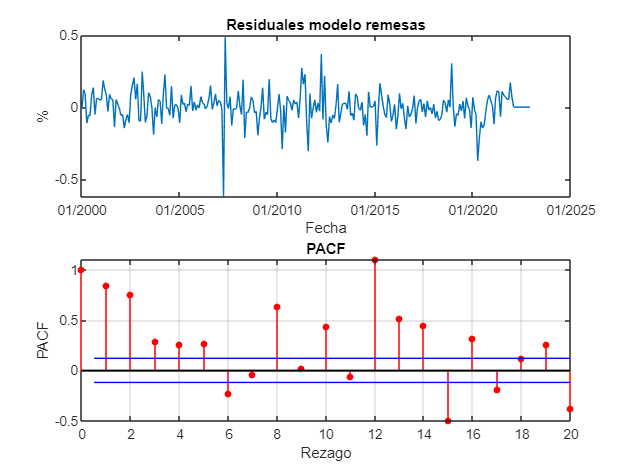

% antes de hacer el pronóstico veamos cómo se comportan los errores y
% obsrrvemos si estos son normales para crear una banda deconfianza:

tributarios.residualesAIC(1:265) = infer(MdlAIC,tributarios.residuales_modeloremesas);

%inspeccion grafica:

figure (3)
subplot(2,1,1)
plot(tributarios.FECHA, tributarios.residualesAIC)
title('Residuales modelo remesas')
xlabel('Fecha') 
ylabel('%') 
datetick('x','mm/yyyy');

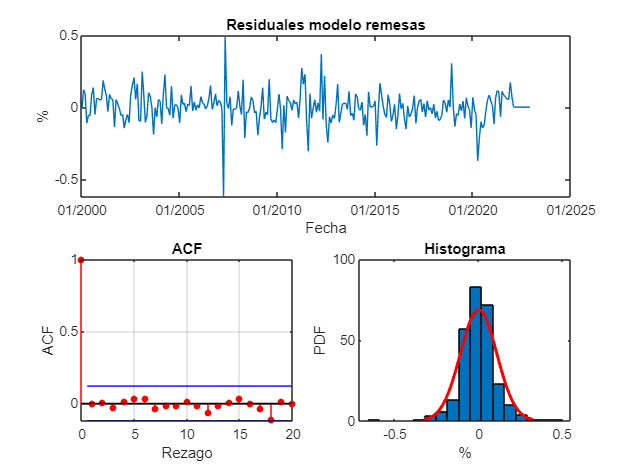


subplot(2,2,3)
autocorr(tributarios.residualesAIC)
ylabel('ACF')
xlabel('Rezago')
title('ACF')

subplot(2,2,4)
histfit(tributarios.residualesAIC)
ylabel('PDF')
xlabel('%')
title('Histograma')



% Q test para los residuales

[h1,P_Value1,Estadistico1,Valor_Critico1] = lbqtest(tributarios.residualesAIC,'lags',[5,10,15])

h1 = 1×3 logical array
   0   0   0


P_Value1 = 1×3
    0.9879    0.9987    0.9995


Estadistico1 = 1×3
    0.6017    1.5676    3.1116


Valor_Critico1 = 1×3
   11.0705   18.3070   24.9958



P_Value1=[P_Value1]';
Estadistico1=[Estadistico1]';
Valor_Critico1=[Valor_Critico1]';

R1 = {'5 Rezagos';'10 Rezagos'; '15 Rezagos'};

Estadistico_Q1=table(P_Value1,Estadistico1,Valor_Critico1,'RowNames',R1)

Estadistico_Q1 = 3×3 table
                  P_Value1    Estadistico1    Valor_Critico1
                  ________    ____________    ______________

    5 Rezagos     0.98793       0.60166            11.07    
    10 Rezagos    0.99871        1.5676           18.307    
    15 Rezagos     0.9995        3.1116           24.996    





%Pruebas de que el error del modelo obtenido anteriormente es Ruido Blanco

    %Buscar como, o si solo con la ACF y la PACF





## Punto 3.6

tributarios.residualesAIC_2=tributarios.residualesAIC.^2

tributarios = 276×12 table
       FECHA        REMESAS      lnREMESAS    Time    time2       MES       lnREMESAS_estimado    REMESAS_estimado    residuales_modeloremesas    dresiduals    residualesAIC    residualesAIC_2
    ___________    __________    _________    ____    _____    _________    __________________    ________________    ________________________    __________    _____________    _______________

    01-Jan-2000    1.8095e+06     14.409        1        1     January            14.763             2.5792e+06               -0.35444                  NaN         -0.0135       

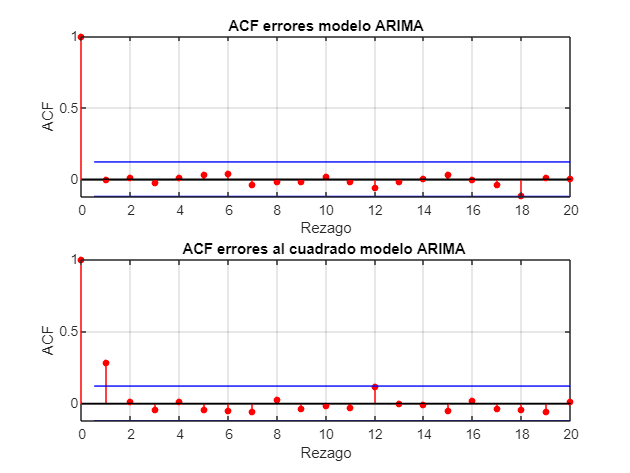

% veamos si esta estimación es sufiicente para eliminar la dependencia
% lineal de las seris y veamos los errores al cuadrado:

figure (3)
subplot(2,1,1)
autocorr(tributarios.residualesAIC)
ylabel('ACF')
xlabel('Rezago')
title('ACF errores modelo ARIMA')

subplot(2,1,2)
autocorr(tributarios.residualesAIC_2)
ylabel('ACF')
xlabel('Rezago')
title('ACF errores al cuadrado modelo ARIMA ')



% Q test para los residuales al cuadrado

[h2,P_Value2,Estadistico2,Valor_Critico2] = lbqtest(tributarios.residualesAIC_2,'lags',[5,10,15])

h2 = 1×3 logical array
   1   1   1


P_Value2 =     0.0002    0.0035    0.0078


Estadistico2 =    24.0144   26.1696   31.3775


Valor_Critico2 =    11.0705   18.3070   24.9958



P_Value2=[P_Value2]';
Estadistico2=[Estadistico2]';
Valor_Critico2=[Valor_Critico2]';

R2 = {'5 Rezagos';'10 Rezagos'; '15 Rezagos'};

Estadistico_Q1=table(P_Value2,Estadistico2,Valor_Critico2,'RowNames',R2)

Estadistico_Q1 = 3×3 table
                   P_Value2     Estadistico2    Valor_Critico2
                  __________    ____________    ______________

    5 Rezagos     0.00021574       24.014            11.07    
    10 Rezagos     0.0035187        26.17           18.307    
    15 Rezagos     0.0078172       31.378           24.996    



[h,pvalue,stat,cvalue]=archtest(tributarios.residualesAIC,'lags',[1,2]) 

h = 1×2 logical array
   1   1


pvalue = 	1.0e+-5 *

    0.1930    0.5683


stat =    22.6633   24.1561


cvalue =     3.8415    5.9915



%% modeloaic
CondVarMdlARCH1 = garch(0,1)

CondVarMdlARCH1 =   garch with properties:

     Description: "GARCH(0,1) Conditional Variance Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 0
               Q: 1
        Constant: NaN
           GARCH: {}
            ARCH: {NaN} at lag [1]
          Offset: 0

MdlAIC.Variance = CondVarMdlARCH1;
[MdlARCH1,~,logL1]  = estimate(MdlAIC,tributarios.residuales_modeloremesas);

 
    ARIMA(12,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    0.0018183          0             Inf          0   

 
 
    GARCH(0,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.011117      0.0005287        21.026      3.7777e-98
    ARCH{1}     0.069871       0.034988         1.997        0.045827



## Punto 3.7

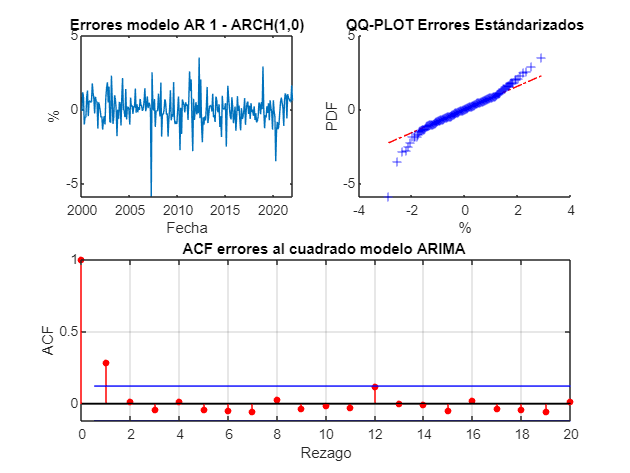

%%Revisar si los errores estimados del modelo resultado en el punto 3.6
%%tienen efectos ARCH, GARCH. Para esto, se usa otra vez el Q-test.


[tributarios.error1(1:265),tributarios.varianza1(1:265)] = infer(MdlARCH1,tributarios.residuales_modeloremesas);
tributarios.errorSt1= (tributarios.error1)./sqrt(tributarios.varianza1);
tributarios.errorSt1_2= (tributarios.errorSt1).^2;

figure (3)
subplot(2,2,1)
plot(tributarios.FECHA,tributarios.errorSt1)
ylabel('%')
xlabel('Fecha')
title('Errores modelo AR 1 - ARCH(1,0)')


subplot(2,2,2)
qqplot(tributarios.errorSt1)
ylabel('PDF')
xlabel('%')
title('QQ-PLOT Errores Estándarizados')

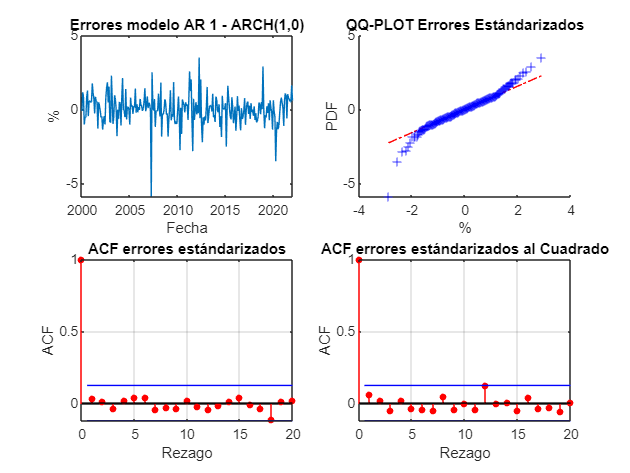


subplot(2,2,3)
autocorr(tributarios.errorSt1)
ylabel('ACF')
xlabel('Rezago')
title('ACF errores estándarizados')

subplot(2,2,4)
autocorr(tributarios.errorSt1_2)
ylabel('ACF')
xlabel('Rezago')
title('ACF errores estándarizados al Cuadrado')


% Ahora veamos el test de Ljiun -Box

% Q test para los residuales

[h3,P_Value3,Estadistico3,Valor_Critico3] = lbqtest(tributarios.errorSt1_2,'lags',[5,10,15])

h3 = 1×3 logical array
   0   0   0


P_Value3 =     0.8231    0.9206    0.7975


Estadistico3 =     2.1845    4.5251   10.3454


Valor_Critico3 =    11.0705   18.3070   24.9958



P_Value3=[P_Value3]';
Estadistico3=[Estadistico3]';
Valor_Critico3=[Valor_Critico3]';

R3 = {'5 Rezagos';'10 Rezagos'; '15 Rezagos'};

Estadistico_Q3=table(P_Value3,Estadistico3,Valor_Critico3,'RowNames',R3)

Estadistico_Q3 = 3×3 table
                  P_Value3    Estadistico3    Valor_Critico3
                  ________    ____________    ______________

    5 Rezagos     0.82307        2.1845            11.07    
    10 Rezagos    0.92057        4.5251           18.307    
    15 Rezagos    0.79747        10.345           24.996    


## Punto 3.8

%Hacer pronostico.


